Multidimensional compare: we compare a barcode island against the theory. The barcode island contains a number of elements. (Possibly move this to main hca repository)

Start with matrix of barcodes (from consensus_real_data.mlx)

ix = 3;
tic
import Core.barcode_island_consensus;
[multiDimBar,Z , allscores] = barcode_island_consensus(barcodeGen,cGenAll, ix, 300);


toc

Elapsed time is 0.060300 seconds.


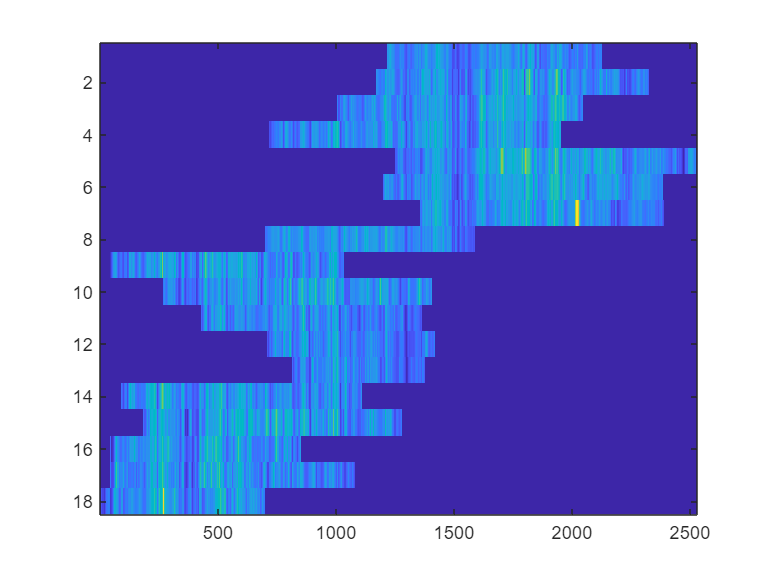

consensus = nanmean(multiDimBar);

figure,imagesc(multiDimBar)



% Compare all the barcodes against the consensus. (No re-scaling)

import SignalRegistration.masked_multidim_pcc_corr;
[ xcorrs, numElts ] = masked_multidim_pcc_corr( multiDimBar',consensus',~isnan(multiDimBar)',~isnan(consensus)',300);


Realignment step:

% with re-scaling
barC = barcodeGen(cGenAll{ix}.idx);
initialStretch = cellfun(@(x) x.bestBarStretch,cGenAll{ix}.comparisonStruct);
% barC = cell(1,size(multiDimBar,1));
% for i=1:size(multiDimBar,1)
%     barC{i}.rawBarcode = multiDimBar(i,:);
%     barC{i}.rawBarcode = barC{i}.rawBarcode(~isnan( barC{i}.rawBarcode));
%     barC{i}.rawBitmask = ~isnan( barC{i}.rawBarcode);
%     barC{i}.rawBarcode(isnan(barC{i}.rawBarcode)) = 0;
% end

thr = [];
thr(1).rawBarcode = consensus(~isnan(consensus));
thr(1).rawBitmask = ~isnan(thr(1).rawBarcode) ;
thr(1).isLinearTF = 1;

sF = 0.85:0.01:1.15;

import Core.rescale_barcode_data;
[barCRescaled] = rescale_barcode_data(barC,sF,initialStretch);

sets.comparisonMethod = 'mass_pcc';
sets.w = nan;
import CBT.Hca.Core.Comparison.hca_compare_distance;
[rezMaxMP] = hca_compare_distance(barCRescaled, thr, sets );
    
% create overlap table
%     info: {'1)PCC, 2) Pos, 3) Or, 4) SecondPos 5) Len '}
vals = double(zeros(size(rezMaxMP{1}{1},1),4));
score = zeros(size(rezMaxMP{1}{1},1),1);
for i=1:length(barCRescaled)
    [maxV,maxPos] = max(rezMaxMP{1}{1}(i,:));
    posStart = double(rezMaxMP{1}{2}(i,maxPos));
    posStop = double(rezMaxMP{1}{2}(i,maxPos)+length(barCRescaled{i}.rescaled{maxPos}.rawBarcode)-1);
    posOr = double(rezMaxMP{1}{3}(i,maxPos));
    curSF =  initialStretch(i)*sF(maxPos);
    score(i) = maxV;

    vals(i,:) = [posStart posStop posOr curSF]; % all these positions are w.r.t. the consensus

    stats.posdif(i) = cGenAll{ix}.comparisonStruct{i}.pos-posStart;
    stats.ordif(i) = isequal(cGenAll{ix}.comparisonStruct{i}.or,posOr);
    stats.sfDif(i) = sF(maxPos);
end

import Plot.islandsPosStruct;
cGenNew{1}.comparisonStruct = islandsPosStruct({vals},{barIslands{ix}});
cGenNew{1}.idx = cGenAll{ix}.idx;
import Core.barcode_island_consensus;
multiDimBarNew = barcode_island_consensus(barcodeGen,cGenNew, 1, 300);

consensusNew = nanmean(multiDimBarNew);


% % now can compare new positions vs old positions - perhaps something is
% % completely wrongly placed?
%    % factor & orientation
%    %%
%     selBarId = 4; % choose sth as root
% 
%     bbS = vals(selBarId,4);  % best bar stretch (bbS) along the theory
%     bbO = (vals(selBarId,3)~=barcodeIslandsData{ix}(selBarId,3))+1; % orientation w.r.t. theory
% 
%     import Core.update_sf_barset;
%    [bbSAll] = update_sf_barset(barcodeIslandsData{ix}, bbS/barcodeIslandsData{ix}(selBarId,4), bbO,selBarId);
% 
%     % need to also update positions for all the synCur barcodes based on
% %     import Core.synth_to_table;
% %     [tableS] = synth_to_table(compI);
% 
%     % update synth table. Want to have the same
%     [tableSUpd] = update_sf_barset(vals, table(selBarId,4)/bbS, 1);

Error using  / 
Arguments must be numeric, char, or logical.



%     bbSAll(:,1:2) = bbSAll(:,1:2)-bbSAll(selBarId,1)+tableSUpd(selBarId,1); %
%    
%     bestPosFound = bbSAll(:,1);
%     
%     posTrue = tableSUpd(:,1);
% 
%     posDif = posTrue-bestPosFound;
% figure,plot(posDif)



Now compare against theory


import SignalRegistration.masked_multidim_pcc_corr;
[ xcorrsT, numEltsT ] = masked_multidim_pcc_corr( multiDimBar',theoryStruct.rawBarcode',~isnan(multiDimBar)',~isnan(theoryStruct.rawBarcode)',300);


Re-scale theories

sF = 0.8:0.025:1.2;
theoryStruct.rawBitmask = zeros(1,length(theoryStruct.rawBarcode));
import Core.rescale_barcode_data;
[tsRescaled] = rescale_barcode_data({theoryStruct},sF);

Calculate PCCs. Todo: maybe don't save everything since this can be quite big matrices. Only the best?

xcorrsT = cell(1,length(tsRescaled{1}.rescaled));
for i=1:length(tsRescaled{1}.rescaled)
    [ xcorrsT{i}, ~ ] = masked_multidim_pcc_corr( multiDimBar',tsRescaled{1}.rescaled{i}.rawBarcode',~isnan(multiDimBar)',~isnan(tsRescaled{1}.rescaled{i}.rawBarcode)',300);
end

% Find best re-scaling factor. 1. For

Find best scaling factors & position. Todo: Use Stouffer score, since each barcode is of different length 

zMethod = 'meanpcc';
scoreSingle = cell(1,length(xcorrsT));
for i=1:length(xcorrsT)
%     [maxScore,maxPos] = max(xcorrsT{i},[],1);
    % first take max over 3rd dim
    [scoreMaxOr,scoreMaxOrPos] = max(xcorrsT{i},[],3);
    switch zMethod
        %             case 'stouffer'
        %             case 'fisher'
        case 'meanpcc'
            scoreSingle{i} = mean(scoreMaxOr,2);
        otherwise
            error('No such method for combining p-values')
    end
end

maxCoefs = cellfun(@(x) max(x),scoreSingle);

[pccMaxB,pccMaxSFmean] = max(maxCoefs);
sFmax = sF(pccMaxSFmean);

Optimal positions

zMethod = 'meanpcc';
scoreSingleOptimal = cell(1,length(xcorrsT));
for i=1:length(xcorrsT)
%     [maxScore,maxPos] = max(xcorrsT{i},[],1);
    % first take max over 3rd dim
    [scoreMaxOr,scoreMaxOrPos] = max(xcorrsT{i},[],3);
    [maxSPosInd,maxSPos] = max(scoreMaxOr,[],1);
    switch zMethod
        %             case 'stouffer'
        %             case 'fisher'
        case 'meanpcc'
            scoreSingleOptimal{i} = mean(maxSPosInd);
        otherwise
            error('No such method for combining p-values')
    end
end

maxCoefsSingleOptimal = cellfun(@(x) max(x),scoreSingleOptimal);

[pccMax,pccMaxSF] = max(maxCoefsSingleOptimal);
sFmax = sF(pccMaxSF);

Now the same for consensus against theory

xcorrsBest = cell(1,length(tsRescaled{1}.rescaled));
for i=1:length(tsRescaled{1}.rescaled)
    [ xcorrsBest{i}, ~ ] = masked_multidim_pcc_corr( consensus',tsRescaled{1}.rescaled{i}.rawBarcode',~isnan(consensus)',~isnan(tsRescaled{1}.rescaled{i}.rawBarcode)',300);
end

zMethod = 'meanpcc';
scoreSingleConsensus = cell(1,length(xcorrsBest));
for i=1:length(xcorrsBest)
    [maxScore,maxPos] = max(xcorrsBest{i},[],1);
    % first take max over 3rd dim
    [scoreMaxOr,scoreMaxOrPos] = max(xcorrsBest{i},[],3);
    switch zMethod
        %             case 'stouffer'
        %             case 'fisher'
        case 'meanpcc'
            scoreSingleConsensus{i} = mean(scoreMaxOr,2);
        otherwise
            error('No such method for combining p-values')
    end
end

maxCoefsConsensus = cellfun(@(x) max(x),scoreSingleConsensus);

Now final idea "Devil's advocate" mean score for each of the pixels

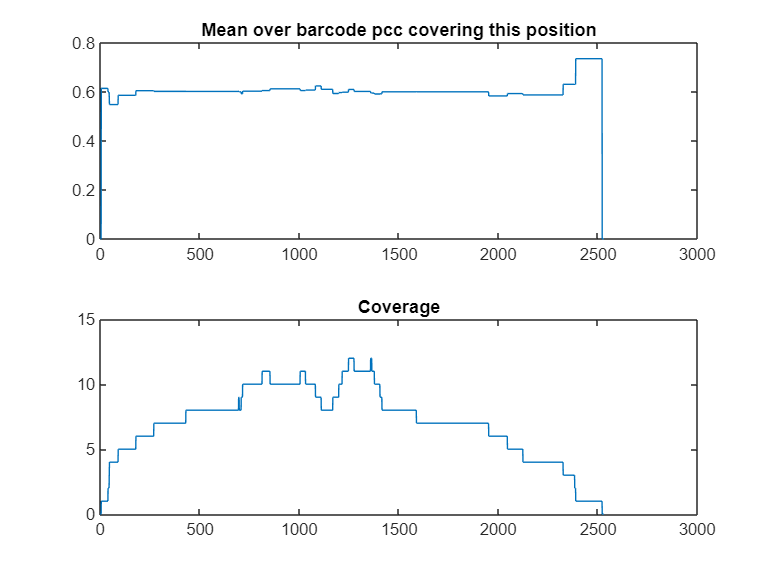

[scoreMaxOr,scoreMaxOrPos] = max(xcorrsT{pccMaxSFmean},[],3);
scoreS = mean(scoreMaxOr,2);
[bS,bestPos] = max(scoreS);

meanPos = zeros(1,length(consensus));
for i=1:length(consensus)
    curBars = find(~isnan(multiDimBar(:,i)));
    if ~isempty(curBars)
        meanPos(i) = mean(scoreMaxOr(bestPos,curBars));
    end
    % use the best position from mean of the barcodes
%     pccMaxSFmean
%     % first take max over 3rd dim
%     [scoreMaxOr,scoreMaxOrPos] = max(xcorrsT{i},[],3);
%     [maxSPosInd,maxSPos] = max(scoreMaxOr,[],1);
 

end
figure,tiledlayout(2,1);
nexttile
plot(meanPos)
title('Mean over barcode pcc covering this position')
nexttile
plot(sum(~isnan(multiDimBar)))
title('Coverage')

Final plot

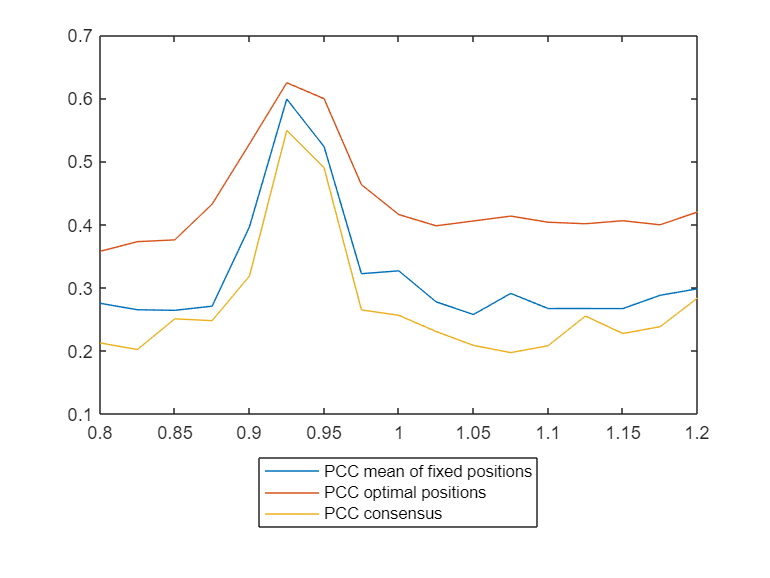

figure,plot(sF,maxCoefs);
hold on
plot(sF,maxCoefsSingleOptimal)
plot(sF,maxCoefsConsensus)
legend({'PCC mean of fixed positions','PCC optimal positions','PCC consensus'},'Location','southoutside')